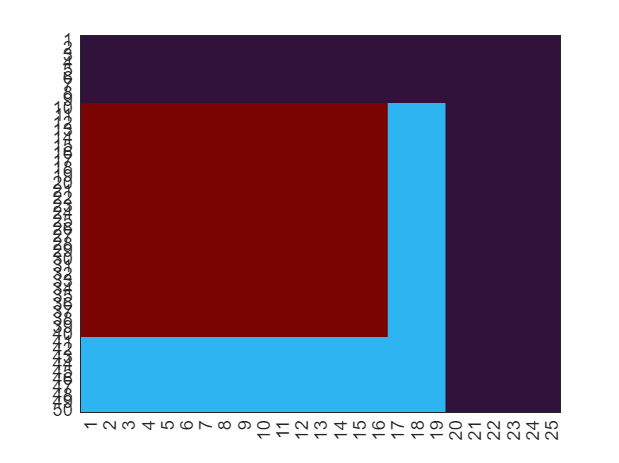

%basci para
dx=0.0025;dy=0.00125;dt=1;
dxx=dx*dx;dyy=dy*dy;
lambda_w=0;lambda_e=0;lambda_s=0;lambda_n=0;
lambda_al=200;lambda_steel=50;lambda_air=3;
rhoc_al=2790*881;rhoc_steel=7840*465;rhoc_air=1.2;
tem_al=600;tem_steel=20;tem_air=20;

%mesh
N_x=25;
N_y=50;
z=4;

%define
% t=zeros(N_x*N_y,1);
t_neo=zeros(N_x*N_y,1);
b=zeros(N_x*N_y,1);
A=zeros(N_x*N_y,N_x*N_y);
t_para=zeros(N_y,N_x);
temp=zeros(N_y,N_x);
temp_neo=zeros(N_y,N_x);
E=zeros(1,100);
F=zeros(1,100);
flag= 1;
dtemp_neo=0;
dtemp=0;
ddtemp=0;
itemp=0;

%inital condition
% material=zeros(N_y,N_x);
lambda=zeros(N_y,N_x);
rhocdt=zeros(N_y,N_x);
q=zeros(N_y,N_x);
%al
% material(:,:)=0.4;
temp_neo(9:N_y-9,1:16)=tem_al;
lambda(9:N_y-9,1:16)=lambda_al;
rhocdt(9:N_y-9,1:16)=rhoc_al/dt;

%cup
% material(:,N_x-8:N_x-5)=0.5;
% material(N_y-9:N_y,:)=0.5;
temp_neo(:,N_x-8:N_x-5)=tem_steel;
temp_neo(N_y-9:N_y,:)=tem_steel;
lambda(:,N_x-8:N_x-5)=lambda_steel;
lambda(N_y-9:N_y,:)=lambda_steel;
rhocdt(:,N_x-8:N_x-5)=rhoc_steel/dt;
rhocdt(N_y-9:N_y,:)=rhoc_steel/dt;
q(9:N_y,N_x-6)=1000000000/dt;
q(9:N_y,N_x-7)=250000000/dt;
%air
% material(1:9,:)=0.001;
% material(:,N_x-5:N_x)=0.001;
temp_neo(1:9,:)=tem_air;
temp_neo(:,N_x-5:N_x)=tem_air;
lambda(1:9,:)=lambda_air;
lambda(:,N_x-5:N_x)=lambda_air;
rhocdt(1:9,:)=rhoc_air/dt;
rhocdt(:,N_x-5:N_x)=rhoc_air/dt;

t=temp_neo(:);

 heatmap(lambda,'ColorbarVisible','off','GridVisible','off','Colormap',turbo);

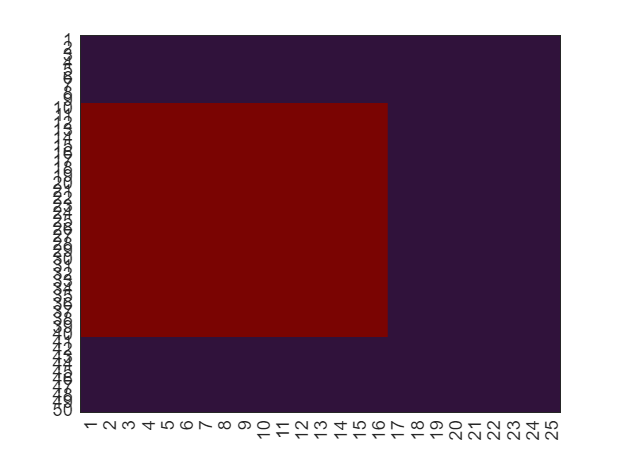

% 
 heatmap(temp_neo,'ColorbarVisible','off','GridVisible','off','Colormap',turbo);

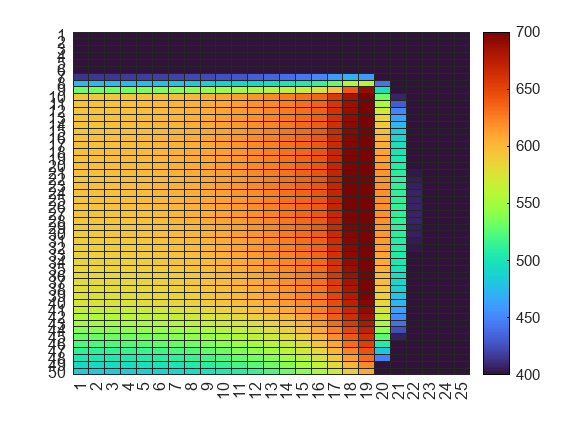

% fo=1;


for time=1:100

    for y=1:1:N_y
        for x=1:1:N_x

        
            %n
            if y>1
                lambda_n=min(lambda(y,x),lambda(y-1,x));
                t_para(y-1,x)=lambda_n/dyy;
            else
%                 lambda_n=0;
         %       t_para(y,x)=t_para(y,x)+lambda_n/dyy;
            end

            %s
            if y<N_y
                lambda_s=min(lambda(y,x),lambda(y+1,x));
                t_para(y+1,x)=lambda_s/dyy;
            else
                lambda_s=1;
%                  t_para(y,x)=t_para(y,x)+lambda_s/dyy;
            end

            %w
            if x>1
                lambda_w=min(lambda(y,x),lambda(y,x-1));
                t_para(y,x-1)=lambda_w/dxx;
            else
                lambda_w=0;
%                 t_para(y,x)=t_para(y,x)+lambda_w/dxx;
            end

            %e
            if x<N_x
                lambda_e=min(lambda(y,x),lambda(y,x+1));
                t_para(y,x+1)=lambda_e/dxx;
            else
%                 lambda_e=0;
%                 t_para(y,x)=t_para(y,x)+lambda_e/dxx;
            end

            %center node para
            t_para(y,x)=-((lambda_w+lambda_e)/dxx+(lambda_n+lambda_s)/dyy+rhocdt(y,x));
            %系数展开成矩阵
            A((y-1)*N_x+x,:)=t_para(:);
            %b
            b((y-1)*N_x+x,1)=-temp_neo(y,x)*rhocdt(y,x)-flag*q(y,x)*abs(sin(time/5*pi+pi/2));
            %重置系数
            t_para=zeros(N_y,N_x);
        end

    end

    t_neo=A\b;
    temp_neo=reshape(t_neo,N_y,N_x);
%      temp_neo(N_y,:)=temp_neo(N_y-1,:);
%pid
    dtemp_neo=temp_neo(26,6)-600;
    ddtemp=dtemp_neo-dtemp;
    dtemp=dtemp_neo;
    itemp=itemp+dtemp;
    flag=-0.001*dtemp-0.01*dtemp-0.0002*itemp;

    if flag>2
        flag=2;
    end
    if flag<0
        flag=0;
    end

    %showcase
    h= heatmap(temp_neo,'Colormap',turbo,'ColorLimits',[400 700]);
%     E(1,time)=t_neo'*rhocdt(:)*dt/10^11;
   E(1,time)= temp_neo(26,6);
   F(1,time)= flag;
    pause(0.1)
    t=temp_neo(:);

    A=zeros(N_x*N_y,N_x*N_y);
end

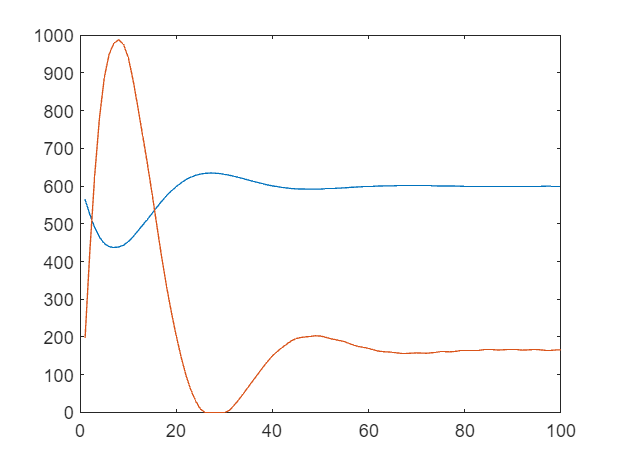

plot(1:100,E);
hold on;
plot(1:100,F*500);